clear;
close all
mex  ./pesq/*.c -output ./bin/PESQ_MEX

使用 'MinGW64 Compiler (C)' 编译。
MEX 已成功完成。


if ispc
    addpath('..\..\audio_files');
    addpath('..\..\sim_environment');
    addpath('..\evaluation');
    addpath('..\auxiliary function');
    addpath('.\pesq');
    addpath('.\bin');
else
    addpath('../../audio_files');
    addpath('../../sim_environment');
    addpath('../evaluation');
    addpath('../auxiliary function');
    addpath('./pesq');
    addpath('./bin');
end



% Generate non reverbrant speech signal + noise signal
% Load ATFs

load Computed_RIRs
% load speech_both 
source_filename{1} = 'speech1.wav';
siglength = 15; 
num_mics = 2;
[source_signals_raw{1}, source_signals_raw{2}] = audioread(source_filename{1});
signal  = resample(source_signals_raw{1},fs_RIR,source_signals_raw{2});
signal = 10*signal(1:siglength*fs_RIR);
speech = fftfilt(RIR_sources,signal,siglength*fs_RIR);
speech_e = fftfilt(RIR_sources(1:800,:),signal,siglength*fs_RIR);
speech_r = fftfilt(RIR_sources(800:end,:),signal,siglength*fs_RIR);

% % generate HRTF signal % HRTF is reveb, larger distortion
% load HRTF
% speech = fftfilt(HRTF(1:600,:),signal,siglength*fs_RIR); 
% % generate non reveb signal, with non reveb noise , has 44 dB snr, least
% % distortion
% load binaural_sig  % non reverbration speech signal
% speech = binaural_sig(1:fs_RIR*siglength,:);


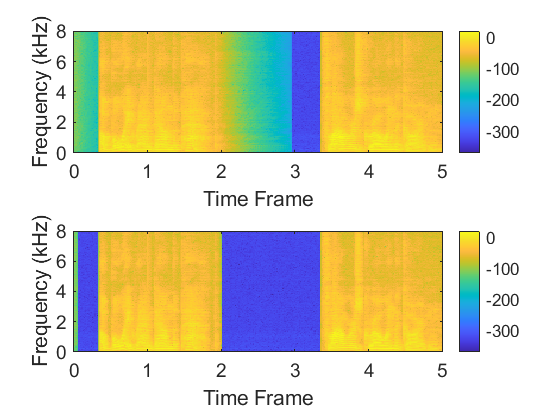

% Generate noise at microphone
 SNR_bubble = -10; 
 SNR_white = 300;
noise_filename{1} = 'Babble_noise1.wav';noise_filename{2} = 'White_noise1.wav';

noise_babble = generate_noise(noise_filename{1},speech(:,1),fs_RIR,SNR_bubble,RIR_noise,siglength);
noise_white  = generate_noise(noise_filename{2},speech(:,1),fs_RIR,SNR_white,RIR_noise,siglength);



%% Exercise 3.1: ## Obtain the noisy microphone signals as outlined in the session document.
%
% SOME CONVENTIONS:
%
% Your clean speech signal should be called "speech" and is a binaural signal such that:
% speech = [speech_L speech_R]  % speech_L and speech_R are the clean binaurally synthesised speech signals from session 1
%
% Your noises should be stored in one binaural variable called "noise"


noise = noise_white + noise_babble;
% noise = noise_babble;
% Create noisy mic signals in the time domain:
noisy_sig = speech + noise ;  %  stacked microphone signals


%soundsc(y_TD,fs_RIR)
snrb = snr(speech(:,1),noise_babble(:,2));
snrw = snr(speech(:,1),noise_white(:,2));
%% Apply WOLA analysis to observe signals in the STFT domain, Apply the SPP.

fs = fs_RIR;    % sampling freq
nfft = 512;    % number of DFT points
window = sqrt(hann(nfft,'periodic')); % analysis window
noverlap = 2;   % factor for overlap. noverlap = 2 corresponds to 50% overlap
time = 0:1/fs:((size(speech,1)-1)/fs);


% ## Apply the WOLA analysis to the noisy mic. signals, the speech, and the noise.
%  reveberation
[y_STFT,f] = WOLA_analysis(noisy_sig,fs_RIR,window,nfft,noverlap) ;% To complete
[n_STFT,~] = WOLA_analysis(noise,fs_RIR,window,nfft,noverlap) ;% To complete
[x_STFT,~] = WOLA_analysis(speech,fs_RIR,window,nfft,noverlap) ;% To complete
[xe_STFT,~] = WOLA_analysis(speech_e,fs_RIR,window,nfft,noverlap) ;% To complete
[xr_STFT,~] = WOLA_analysis(speech_r,fs_RIR,window,nfft,noverlap) ;% To complete

% Observe the STFT
clow = -100; chigh = 10; % lower and upper limits for signal power in spectrogram (can change for different resolutions)
[N_freqs, N_frames] = size(y_STFT(:,:,1));

figure;subplot(2,1,1);
imagesc(time, f/1000, mag2db(abs(x_STFT(:,:,1)))); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')
subplot(2,1,2);
imagesc(time, f/1000, mag2db(abs(xe_STFT(:,:,1)))); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')

% figure;
% imagesc(time, f/1000, mag2db(abs(y_STFT_rev(:,:,1))), [clow, chigh]); colorbar;
% axis xy; set(gca,'fontsize', 14);
% set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')




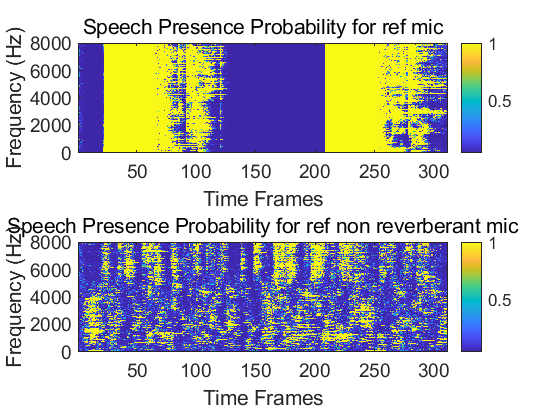

%%
% ## Compute the Speech Presence Probability on the reference microphone
% (you can try the speech-only signal or the noisy-speech in one of the microphones)
% Use the attached spp_calc.m function

% [noisePowMat, SPP] =  spp_calc888(y_STFT(:,:,1));% To complete
[noisePowMat, SPP] =  spp_calc(speech(:,1),nfft,nfft/noverlap);
[noisePowMat_y, SPP_y] =  spp_calc(noisy_sig(:,1),nfft,nfft/noverlap);

% Create perfect VAD - use x_STFT (cheating...)
VAD_th = -60;   % VAD threshold
pVAD = ((mag2db(abs(x_STFT(5,:,1))))>VAD_th).';

% Observe the SPP
figure; subplot(2,1,1);
imagesc(1:N_frames, f,SPP); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');
subplot(2,1,2);
imagesc(1:N_frames, f,SPP_y); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref non reverberant mic');

% %%
% 

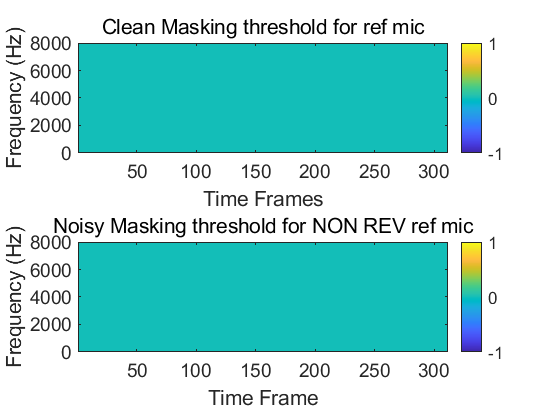

%% observe Tx_mask, TY_mask, TN_mask
TY_Mask = zeros(N_freqs,N_frames);
TX_Mask = zeros(N_freqs,N_frames);
TXE_Mask = zeros(N_freqs,N_frames);
TN_Mask = zeros(N_freqs,N_frames);
noise_spl = zeros(N_freqs,N_frames);
NMR = zeros(N_freqs,N_frames);

% for t = 1:N_frames
% %  use 1st mic speech signal as masker
% %      [TY_Mask(:,t),bark] = mask_cal(y_STFT(:,t,1),f,fs,nfft,t,1);
%    [TX_Mask(:,t),bark] = mask_cal(x_STFT(:,t,1),f,fs,nfft,t,10);
%    noise_spl(:,t) = psd2spl(n_STFT(:,t,1),nfft);
%    NMR_X(:,t) = noise_spl(:,t)-TX_Mask(:,t);          
% end
% for t = 1:N_frames
%  use 1st mic non reverbrant speech signal as masker
%    [TY_Mask(:,t),bark] = mask_cal(y_STFT(:,t,1),f,fs,nfft,t,5);
%    noise_spl(:,t) = psd2spl(n_STFT(:,t,1),nfft);
%    NMR_Y(:,t) = noise_spl(:,t)-TXE_Mask(:,t);          
% end
% Observe the TM
figure; subplot(2,1,1);
imagesc(1:N_frames, f,TX_Mask); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Clean Masking threshold for ref mic');
subplot(2,1,2);
imagesc(1:N_frames, f, TY_Mask); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (Hz)'),...
    title('Noisy Masking threshold for NON REV ref mic');

% figure;subplot(2,1,1);
% imagesc(1:N_frames, f,NMR_X); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('NMR clean');
% subplot(2,1,2);
% imagesc(1:N_frames, f,NMR_Y); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), ...
%     title('NMR noise');


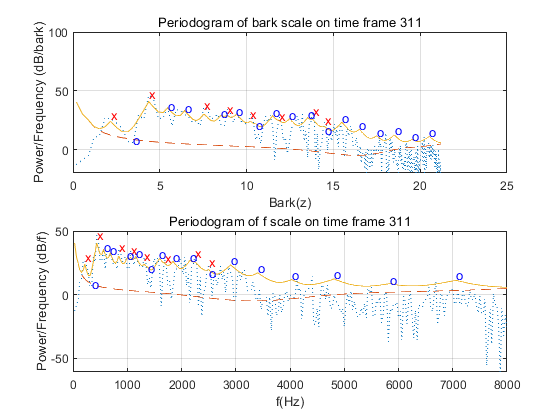

% lambda forgetting factor, SPP_thr update threshold
model = struct('lambda',0.99,'SPP_thr',0.95,'mu',1,'weight',1);
num_mics = size(y_STFT,3);
% % calculate RTF d and diffuse reverberation gama
[h_steer,gama] = RTF_cal(fs_RIR,m_pos,s_pos,num_mics,N_freqs) ;

% implement NR algorithm, use simple spetral subtraction
% TX_Mask = ones(N_freqs,N_frames);
% NMR = ones(N_freqs,N_frames);
[S_pre_MWF,~,~] = NoiseReduction(y_STFT,x_STFT,n_STFT,xe_STFT,xr_STFT,...
                                     SPP,TX_Mask,NMR,model,h_steer,gama);
figure; subplot(2,1,1);
imagesc(1:N_frames,f/1000,mag2db(abs(x_STFT(:,:,1))),[-100 0]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'), title('microphne signal, 1st mic');
subplot(2,1,2); 
imagesc(1:N_frames,f/1000,mag2db(abs(S_pre_MWF(:,:,1))),[-100 0]);
colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); 
xlabel('Time (s)'), ylabel('Frequency (Hz)'),...
title('Enhanced Signal L - MWF');                              
% estimated TX based on primary enhanced speech signal
% use enhanced signal as masker
TS_enhance_Mask = zeros(N_freqs,N_frames);
noise_enhance_spl = zeros(N_freqs,N_frames);
NMR_S= zeros(N_freqs,N_frames);
for t = 1:N_frames
   [TS_enhance_Mask(:,t),bark] = mask_cal(S_pre_MWF(:,t,1),f,fs,nfft,t,10);
   noise_enhance_spl(:,t) = psd2spl(n_STFT(:,t,1),nfft);
   NMR_S(:,t) = noise_enhance_spl(:,t)-TX_Mask(:,t);          
end

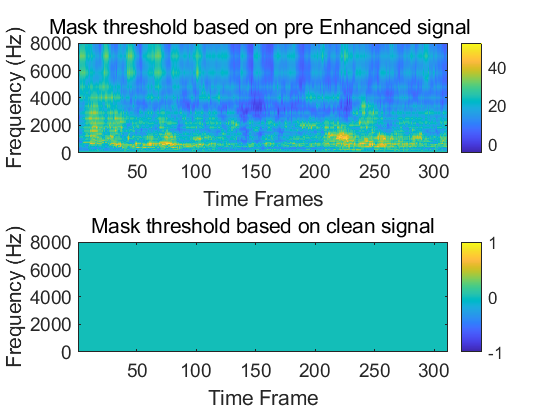

figure; subplot(2,1,1);
 imagesc(1:N_frames, f,TS_enhance_Mask); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), ...
    title('Mask threshold based on pre Enhanced signal ');
subplot(2,1,2);
imagesc(1:N_frames, f, TX_Mask); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (Hz)'),...
    title('Mask threshold based on clean signal');

% implement NR algorithm, use perceptual weighting
model.weight = 4; model.mu = 1;
[S_MWF,X_MWF,N_MWF] = NoiseReduction(y_STFT,xe_STFT,n_STFT,...
              xe_STFT,xr_STFT,SPP,TX_Mask,NMR,model,h_steer,gama);
%TS_enhance_Mask
% Observe processed STFTst

figure; subplot(2,1,1);
imagesc(1:N_frames,f/1000,mag2db(abs( x_STFT(:,:,1)))); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'), title('microphne signal, 1st mic');
S_L_enhanced = S_MWF(:,:,1);
subplot(2,1,2); imagesc(1:N_frames,f/1000,mag2db(abs(S_MWF(:,:,1))), [clow, chigh]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'),title('Enhanced Signal L - MWF');
% figure;
% imagesc(1:N_frames, f,muxx); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Masking threshold for ref mic');

% Apply the synthesis stage of the WOLA framework to obtain the time domain equivalents:
S_MWF(1:end,1:10,:) = 0;
s_mwfL = WOLA_synthesis(S_MWF,window,nfft,noverlap);% To complete (time-domain version of S_mvdr_mwfL_stft)
x_mwfL = WOLA_synthesis(X_MWF,window,nfft,noverlap);% To complete (time-domain version of X_mvdr_mwfL_stft)
n_mwfL = WOLA_synthesis(N_MWF,window,nfft,noverlap);% To complete (time-domain version of N_mvdr_mwfL_stft)

% transform vad to time vad
pvad = repmat(pVAD',N_fft,1); L = size(pvad,2);
vad = zeros((R_fft)*(L-1) + N_fft, 1);
for m = 0:size(pvad,2)-1
    vad((floor(m * R_fft) + 1):floor(m * R_fft + N_fft),:) = pvad(:,m+1)...
        +vad((floor(m * R_fft) + 1):floor(m * R_fft + N_fft),:);
end
vad((vad >=1)) = 1;

% PLOT SIGNALS
figure;
subplot(2,1,1);
plot(speech(:,1)); title('clean signal');
subplot(2,1,2);
plot(real(s_mwfL(:,1)));title('signal after enhancement');
% LISTEN TO SIGNALS!
soundsc(real(s_mwfL(:,1)),fs);
%  soundsc(signal,fs);
%  soundsc(noisy_sig,fs_RIR);
% EVALUATION
enhance_sig = real(s_mwfL(:,1));
noisy_sig_ref = noisy_sig(:,1);
speech_ref = speech(:,1);
%  snr
in.snr =snr(speech(:,1),noise(:,1)); % Compute input SNR
out.snr =snr(s_mwfL(:,1),n_mwfL(:,1)) ;% Compute output SNR
delta.SNR_L = out.snr-in.snr;
in.SI_SNR =SI_SNR(speech(:,1),noise(:,1),1, fs, vad); % Compute input SNR
out.SI_SNR =SI_SNR(s_mwfL(:,1),n_mwfL(:,1),1, fs, vad); ;% Compute output SNR
delta.SI_SNR = out.SI_SNR-in.SI_SNR;
% segsnr
[in.segsnr,in.glosnr]=v_snrseg(noisy_sig_ref,speech_ref,fs,'Vq',0.03); 
[out.segsnr,out.glosnr]=v_snrseg(enhance_sig ,speech_ref,fs,'Vq',0.03); 
delta.segSNR = out.segsnr-in.segsnr;
% spectral distance SD
[in.SD,in.BSD,in.MBSD] = distor_cal(x_STFT,y_STFT,nfft,TX_Mask);
[out.SD,out.BSD,out.MBSD] = distor_cal(x_STFT,S_MWF,nfft,TX_Mask);
delta.SD = out.SD-in.SD; delta.BSD = out.BSD-in.BSD; delta.MBSD = out.MBSD-in.MBSD; 

% PESQ
in.pesq = pesq_mex(speech_ref, noisy_sig_ref, fs, 'wideband');
out.pesq = pesq_mex(speech_ref, enhance_sig, fs, 'wideband');
delta.pesq = out.pesq - in.pesq;
% STOI short time objective Intelligibility Measure
in.stoi  = stoi(speech_ref,noisy_sig_ref, fs);
out.stoi = stoi(speech_ref, enhance_sig, fs);
delta.stoi = out.stoi - in.stoi;
% display 
% disp(deltapesq)
% disp(['delta_SNR = ', num2str(delta_segSNR),' pesq',num2str(delta_pesq),' ,SD_L is ', num2str(SD_L),...
%     ' ,BSD_L is ', num2str(BSD_L), ' ,MBSD is ', num2str(MBSD_L), ' ,weight model is ',num2str(model.weight) ,' ,mu model is ',num2str(model.mu)]);
% 
delta 
model 